# *E.coli *iJO1366 "Glutamate Metabolism Subsystem" (including Glutamine),

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Glutamate Metabolism Subsystem" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1. Glutamate and Glutamine Metabolism **

The purpose of this tutorial is to identify and review the structure and capabilities of the "Glutamate Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-Glutamate and L-Glutamine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## **2. "Glutamate Metabolism" Subsystem **

The ability to synthesize both L-Glutamate and L-Glutamine within *E.coli* has importance since it is the only route to incorporate inorganic nitrogen into the cell structure. In *E.coli* all inorganic nitrogen must be first converted into ammonium ('nh4_c'), which is then incorporated as an amino group of L-Glutamate and L-Glutamine. The amino group from these amino acids is then transferred to other nitrogen containing compounds withint the cell. As we will see later, L-Glutamate is the primary amino donor for most amino acids while L-Glutamine is the primary donor for the synthesis of purines, pyrimidines, amino sugars, histidine, tryptophan, asparagine, NAD+ and *p-*aminobenozoate [5]. 

The reactions associated with the "Glutamate Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
glutamateGlutamineSubSystems = {'Glutamate Metabolism'};
glutamateGlutamineReactions = model.rxns(ismember(model.subSystems,glutamateGlutamineSubSystems));
[tmp,glutamateGlutamine_rxnID] = ismember(glutamateGlutamineReactions,model.rxns);
reactionNames = model.rxnNames(glutamateGlutamine_rxnID);
reactionFormulas = printRxnFormula(model,glutamateGlutamineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',glutamateGlutamineReactions)

T = 6×2 table
                       reactionNames                                     reactionFormulas                        
              ________________________________    _______________________________________________________________

    GLNS      'Glutamine synthetase'              'atp_c + glu__L_c + nh4_c  -> adp_c + gln__L_c + h_c + pi_c '  
    GLUDC     'Glutamate Decarboxylase'           'glu__L_c + h_c  -> 4abut_c + co2_c '                          
    GLUDy     'Glutamate dehydrogenase (NADP)'    'glu__L_c + h2o_c + nadp_c  <=> akg_c + h_c + nadph_c + nh4_c '
    GLUN      'Glutaminase'                       'gln__L_c + h2o_c  -> glu__L_c + nh4_c '                       
    GLUNpp    'Glutaminase'                       'gln__L_p + h2o_p  -> glu__L_p + nh4_p '                       
    GLUSy     'Gl

**Table 1.** The "Glutamate Metabolism" subsystem reaction names and reaction formulas.

The relationships between these reactions can be visualized by creating an Escher map [3] of "Glutamate Metabolism" subsystem as shown below.  

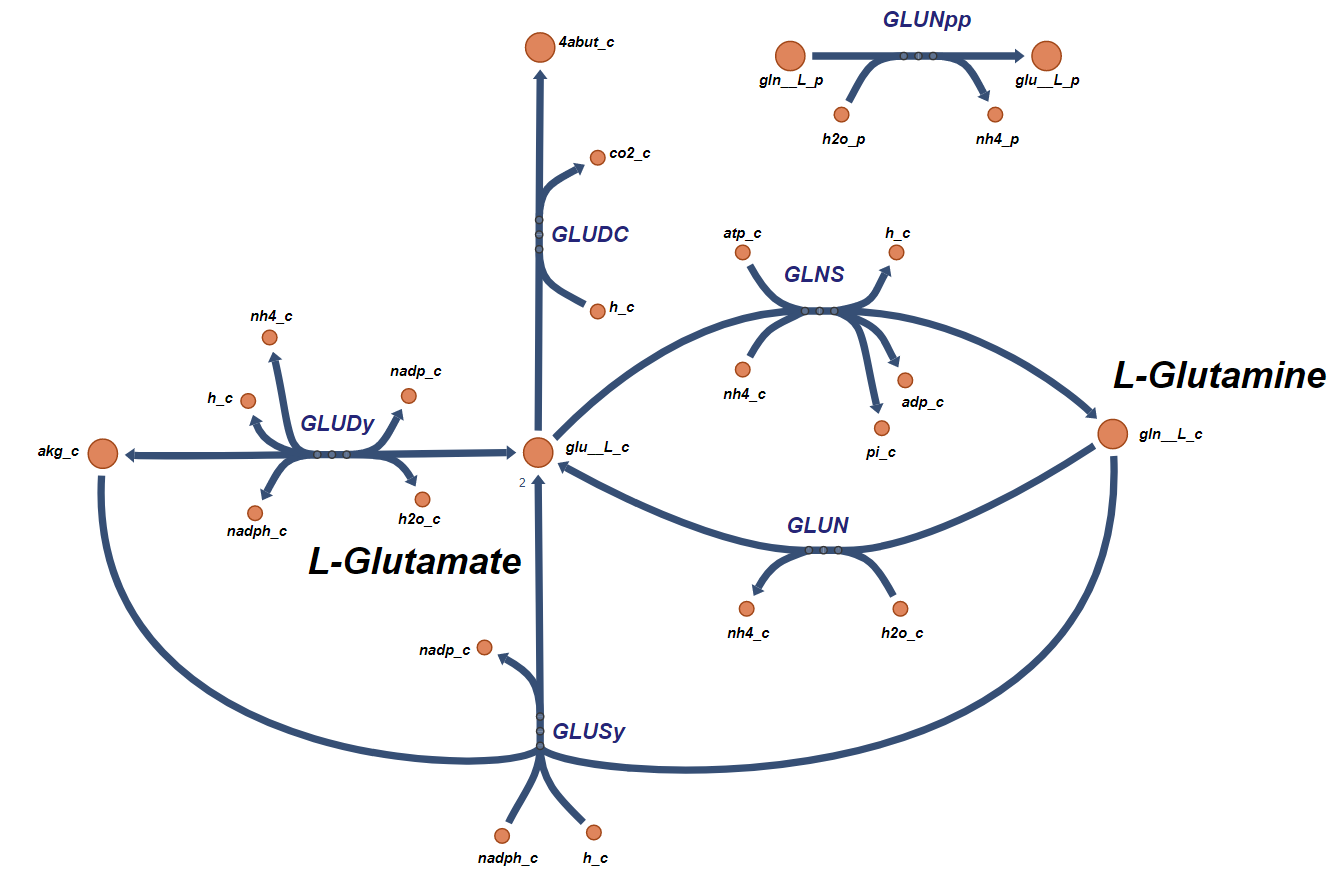

**Figure 1.** The "Glutamate Metabolism" subsystem.

In this figure, the  primary pathway for the biosynthesis of L-Glutamate begins with the precursor "2-oxoacetate" ('akg_c') and includes the single bidirectional reaction 'GLUDy' (Glutamate dehydrogenase (NADP)). Secondary L-Glutamate biosynthesis pathways, 'GLUN' (Glutaminase) and 'GLUSy' (Glutamate synthase (NADPH)), result in the converstion of L-Glutamine to L-Glutamate. 

The primary pathway of biosynthesis for L-Glutamine begins with the precursor "2-oxoacetate" ( 'akg_c') and involves two reactions; 'GLUDy' and "GLNS' (Glutamine synthetase). The last two reactions in this subsystem include 'GLUDC' (Glutamate Decarboxylase) and 'GLUNpp' (Glutaminase). The first of these reactions is part of a pathway in the "Arginine and Proline Metabolism" subsystem which leads to the production of succinate. The second of these reactions, 'GLUNpp",  allows the conversion of periplasmic L-Glutamine ('gln__L_p')  to be converted to periplasmic L-Glutamate ('glu__L_p').

Since both L-Glutamate and L-Glutamine can be amino group donors

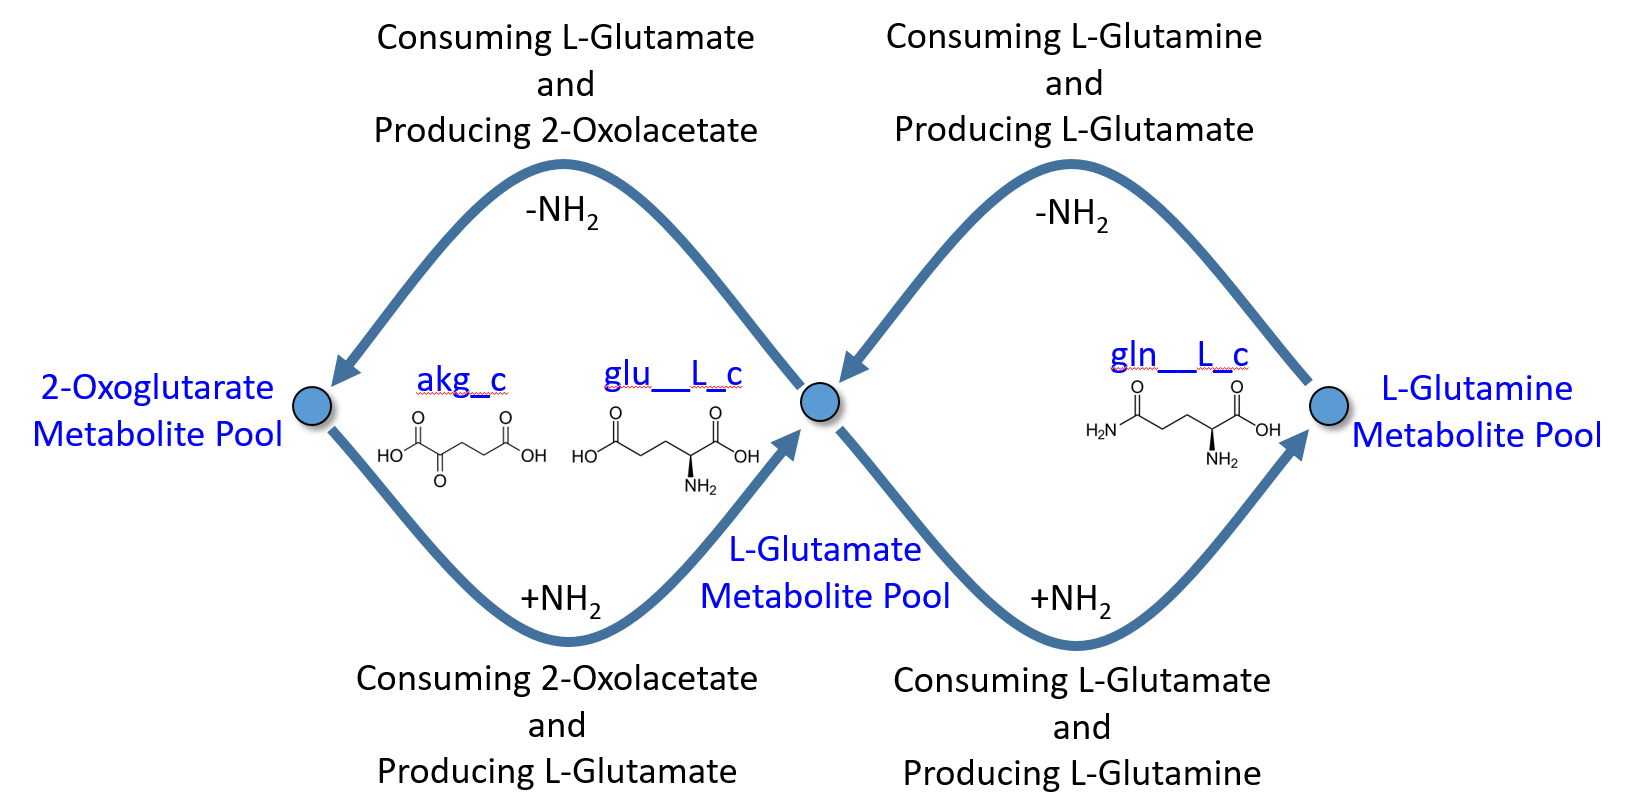

**Figure 2.** The relationship between 2-Oxoglutarate, L-Glutamate, and L-Glutamine.

The term “pool” refers to the concept that there is a certain concentration (pool) of metabolites located within the cell that, in part, determines the kinetic rates of the enzymes. As the concentration of a substrate and/or the needed cofactors increases so does the production of the desired enzymatic product.  Although the concentration of a given metabolite might not be uniform through an entire cellular compartment, it does give a numerical feel for the general operation of a cell. The purpose of the diagram is to show that there is a form of recycling that takes place as both L-Glutamate and L-Glutamine donate amino groups to other pathways within the cell. This recycling occurs because L-Glutamate is the primary amino donor for most amino acids while L-Glutamine is the primary donor for the synthesis of purines, pyrimidines, amino sugars, histidine, tryptophan, asparagine, NAD+ and p-aminobenozoate” [5]. Thus, as L-Glutamate donates its amino group the byproduct is 2-Oxoglutarate and as L-Glutamine donates it’s amino group the byproduct is L-Glutamate.

## **3. L-Glutamate Biosynthesis**

The chemical structure for L-Glutamate (Glutamic acid) is shown below. 

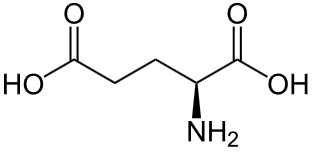

**Figure 3**. The chemical structure of L-Glutamate or Glutamic acid (${\mathrm{C}}_5 {\mathrm{H}}_9 {\mathrm{O}}_4$N) - Wikipedia

L-Glutamate is the primary amino donor for most amino acids and accounts for over 90% of the nitrogen that flows through a cell [4]. Since L-Glutamate is used to provide the amino groups to all the amino acids, we should see a large number of both consuming and producing reactions. We should also expect that a large number of these reaction will be bidirectional, which allows them to operate as either consumers and producers. The consuming and producing reactions for L-glutatmate can be identified using the COBRA toolbox function "surfNet" as shown below.

surfNet(model, 'glu__L_c')


Met #544  glu__L_c, L-Glutamate, C5H8NO4
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

Below is a figure that shows all the "Consuming" and "Producing" reactions associated with L-Glutamate (Glutamate_Biosynthesis_Total.json, Glutamate_Biosynthesis_Total.png or Glutamate_Biosynthesis_Total.svg). 

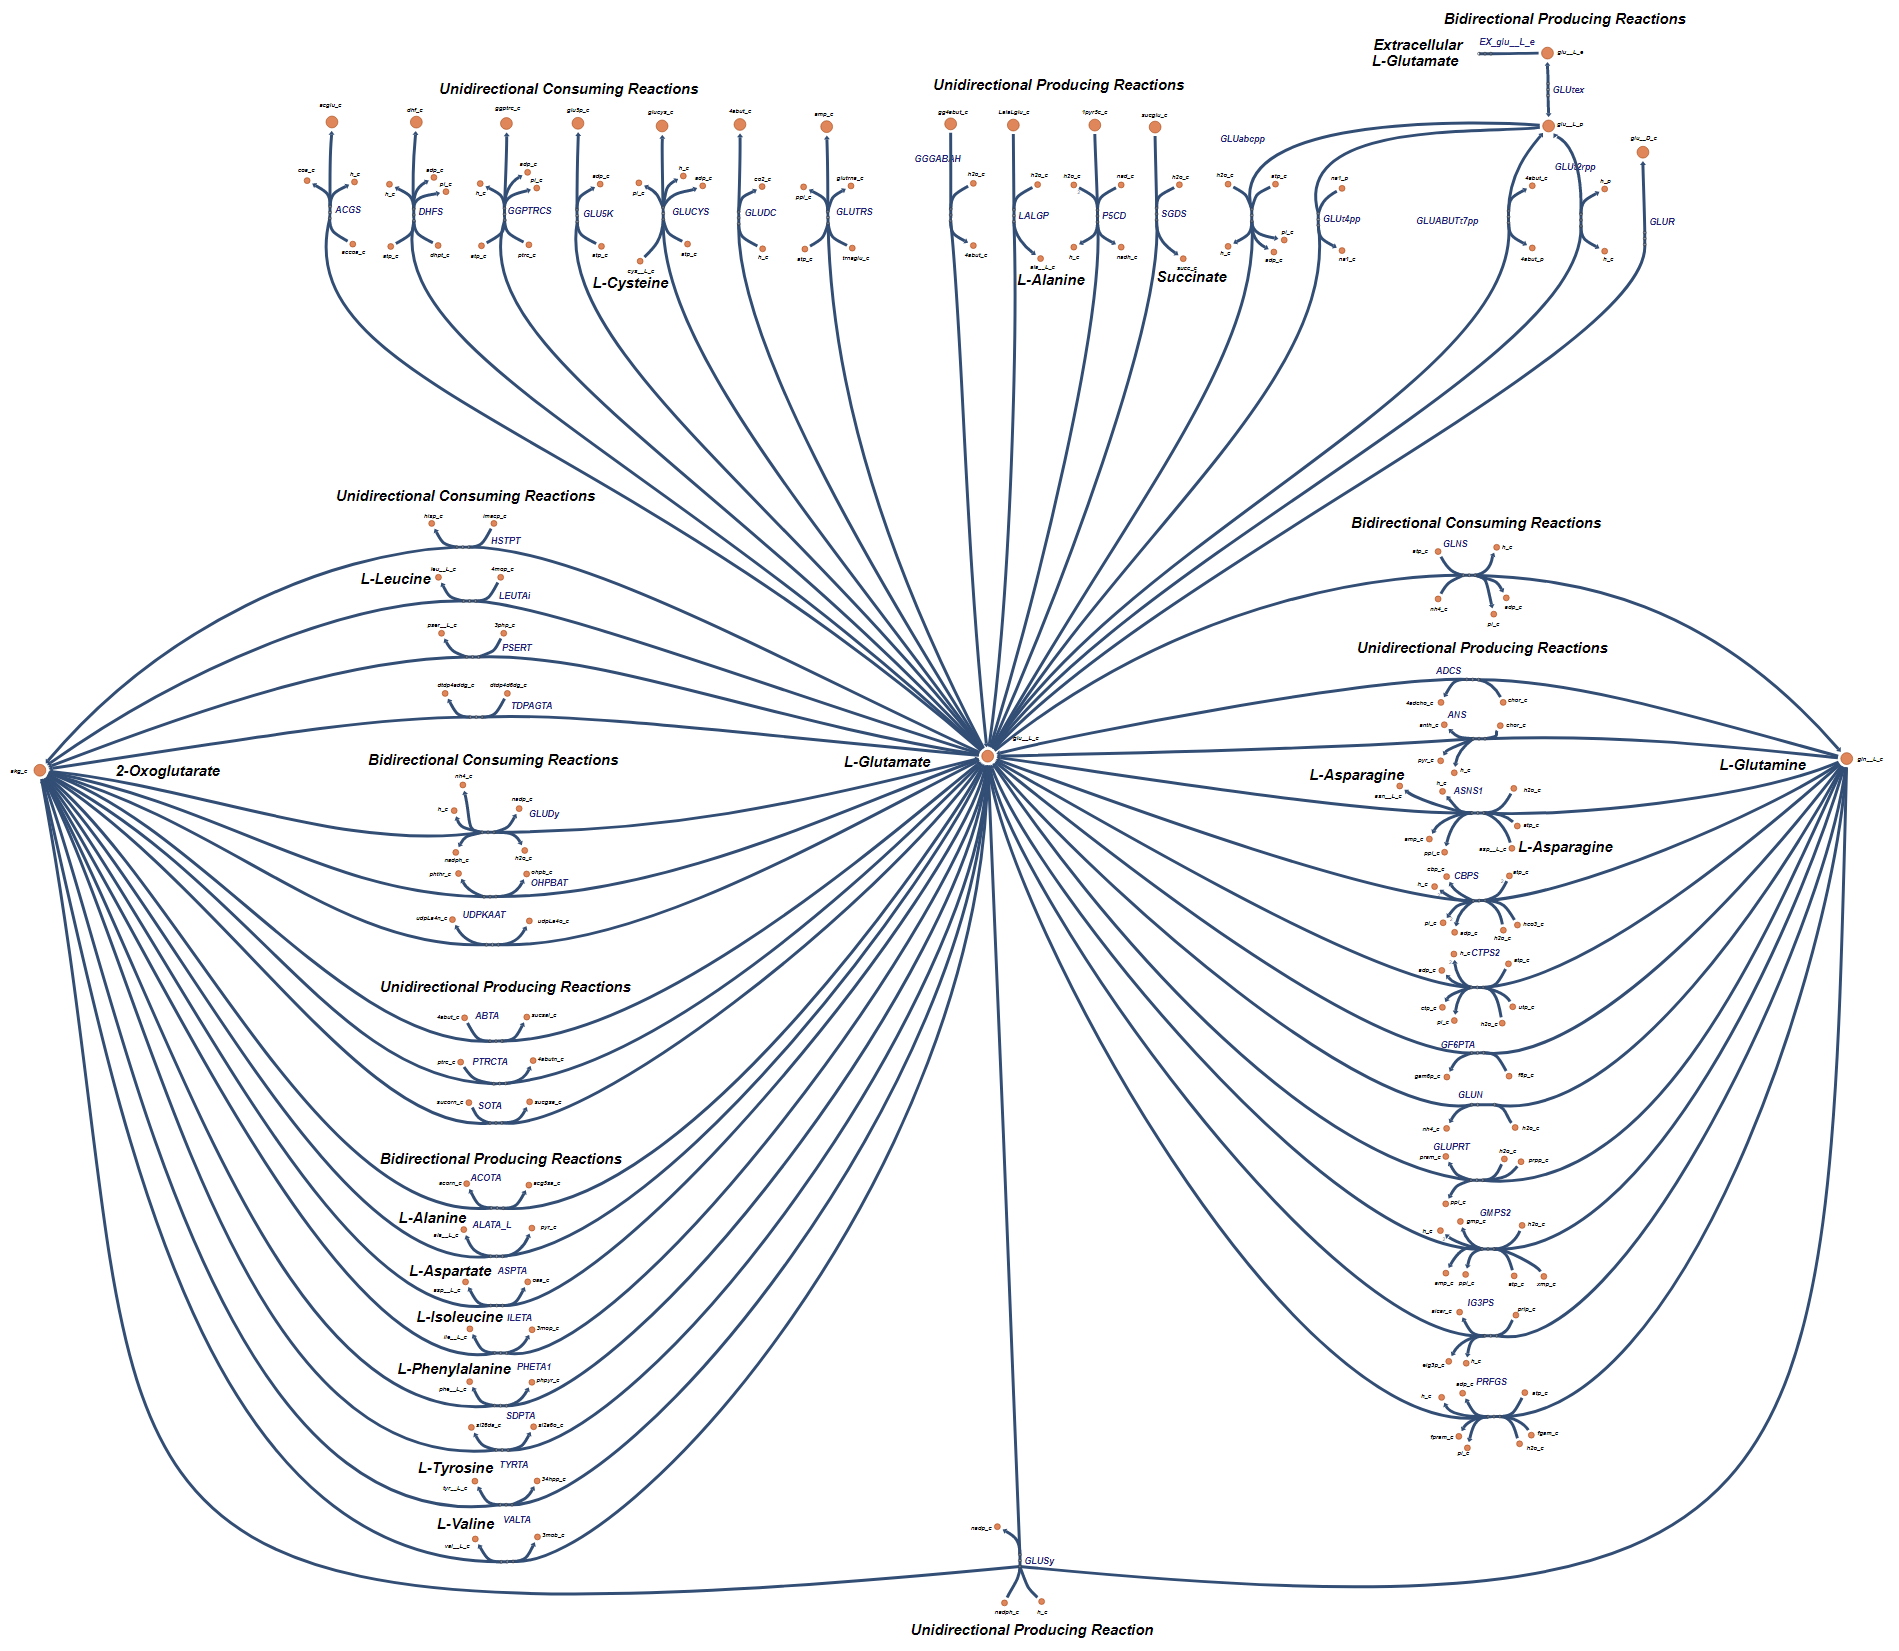

**Figure 4.** All consuming and producing pathways associated with L-Glutamate. 

In this figure, the consuming and producing pathways are marked and labeled if they are unidirectional or bidirectional. 

The value of this designation is seen in the next figure which shows the flux values through the  pathways for aerobic operation. In reading this figure, the flux though unidirectional consuming reactions will aways be positive (red) as the flux moves away from or reducing the L-Glutamate pool. On the other hand, the flux though unidirectional producing reactions will aways be positive (red) as the flux moves towards or adds to the L-Glutamate pool. For the case of the bidirectional "Consuming" reactions, the forward direction is away from the L-Glutamate pool which would show on the figure as positive or red, while a blue color would indicate that the flux is going in the reverse direction adding to the pool. Finally, for the case of a bidirectional "Producing" reaction, the forward direction (red) is towards the L-Glutamate pool with the color blue showing the reverse direction of the flux away from the L-Glutamate pool. (Glutamate_Biosynthesis_Aerobic_Flux.json or Glutamate_Biosynthesis_Aerobic_Flux.svg or Glutamate_Biosynthesis_Aerobic_Flux.png)

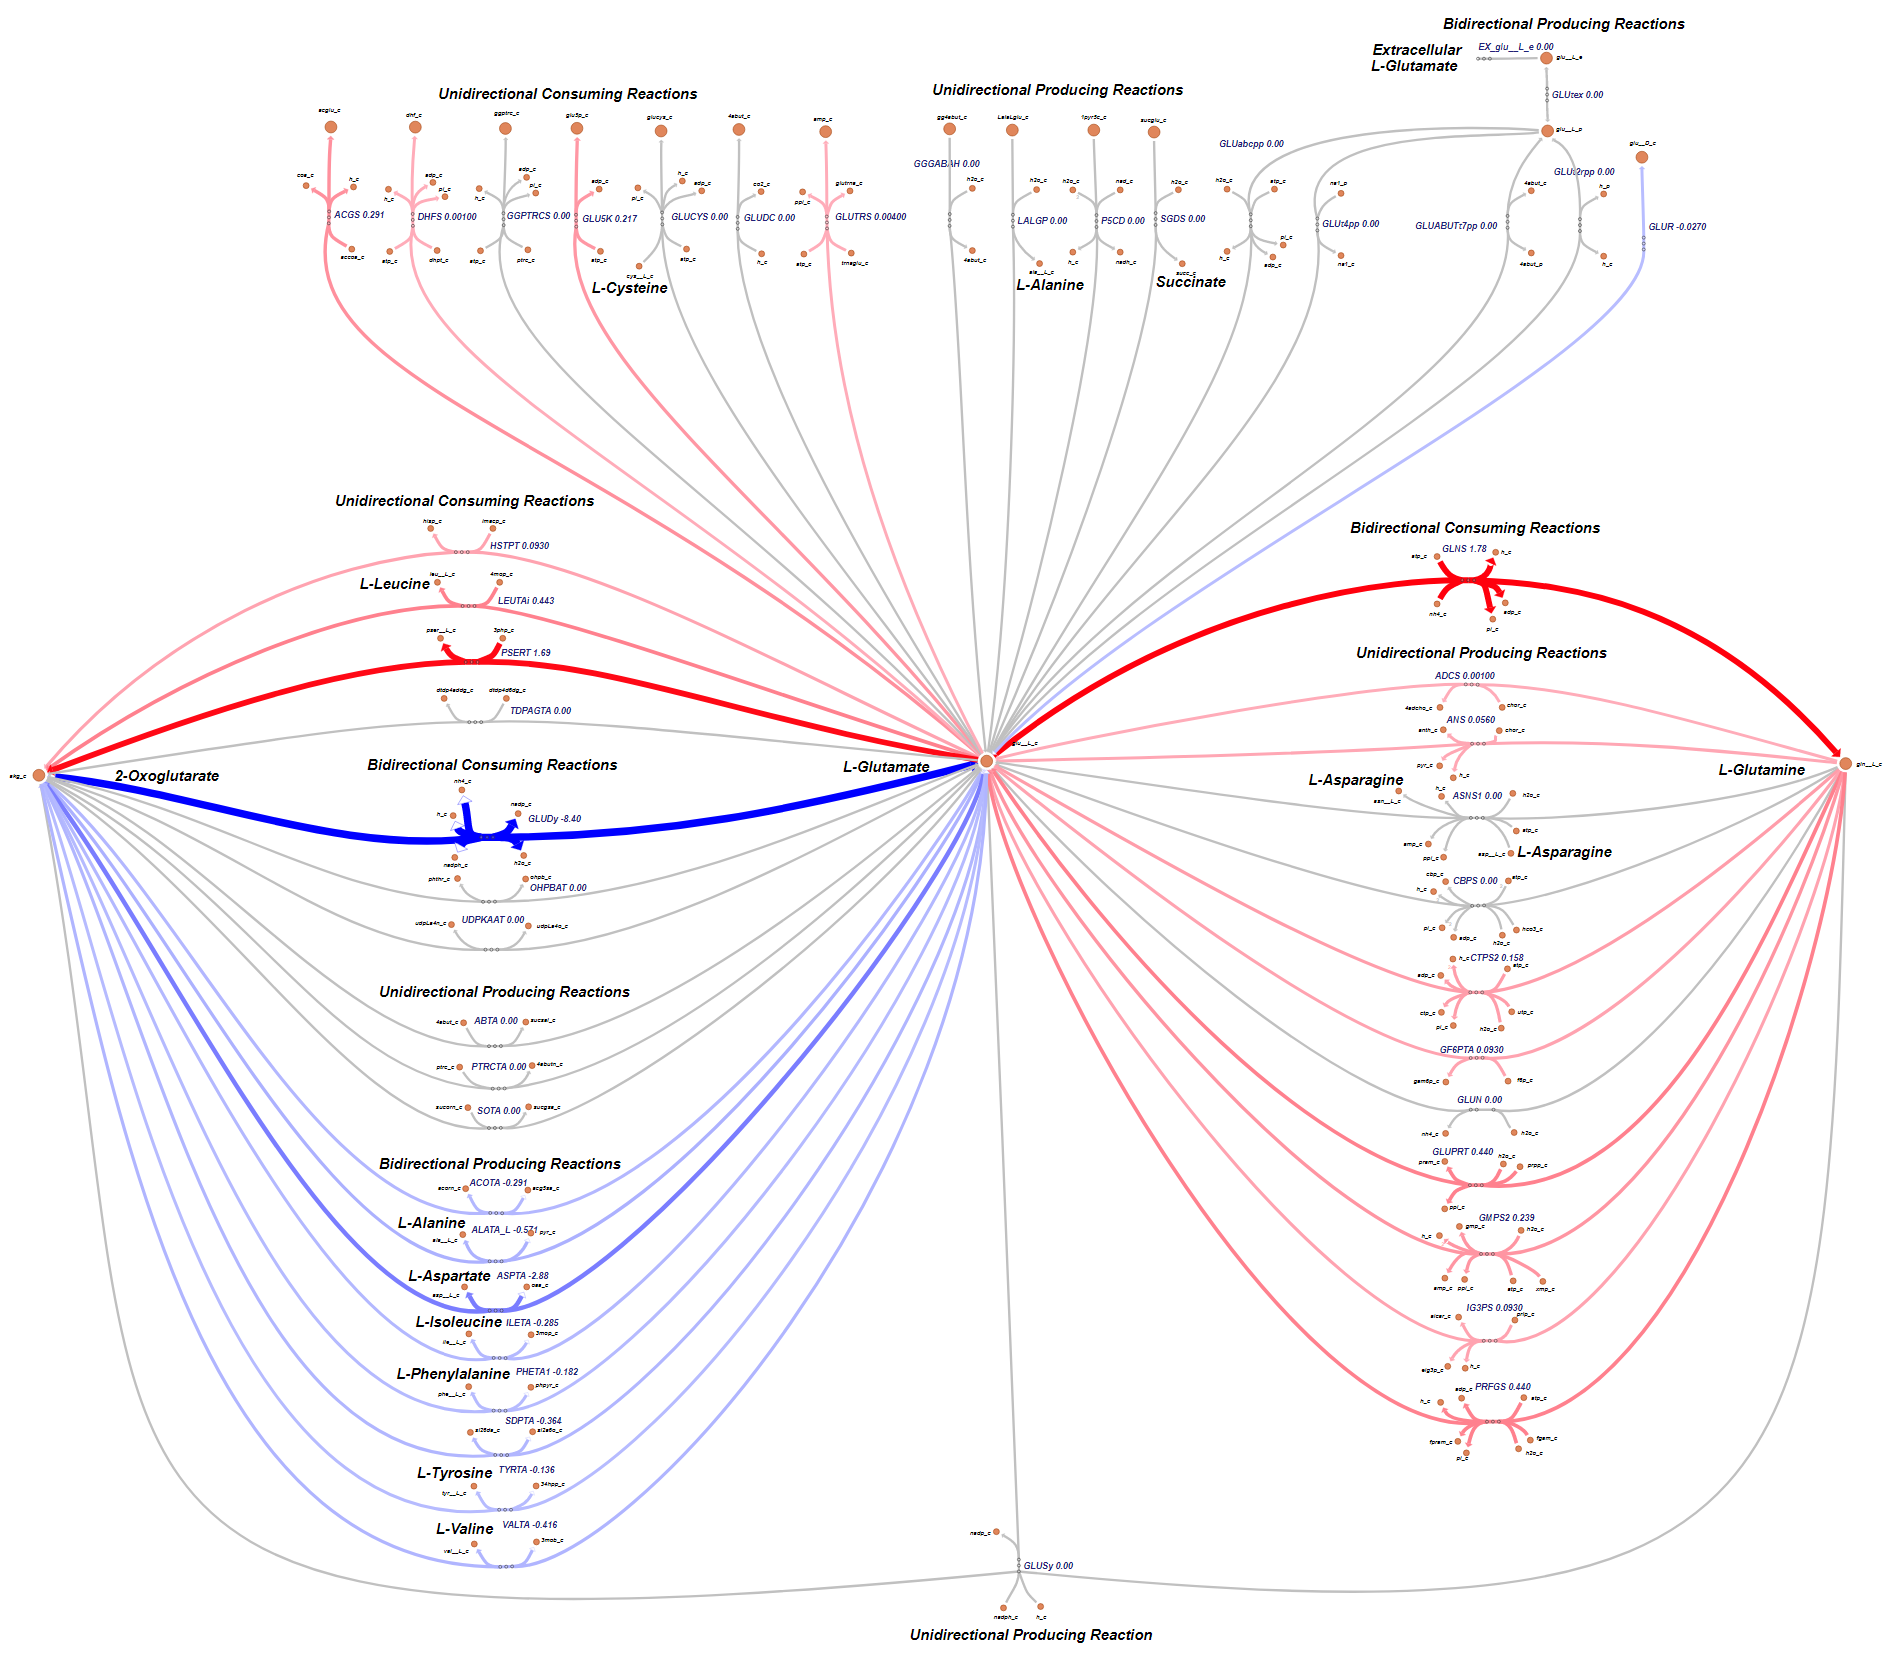

**Figure x.** Aerobic fluxes flowing through the L-Glutamate biosynthesis pathways.

In this figure we can see that the primary pathways for the biosyntheis pathways is through 'GLUDy' (bright red) which is operating in reverse mode. The primary consumer of L-Glutamate is through 'GLNS'  and 'PSERT' (bright red) . From this figure you can see that there are other pathways that both consume and produce L-Glutamate.

The L-Glutamate "Producing reactions" plus the bidriectional "Consuming reactions" are illustrated in the following figure (the biomass reactions are not included).

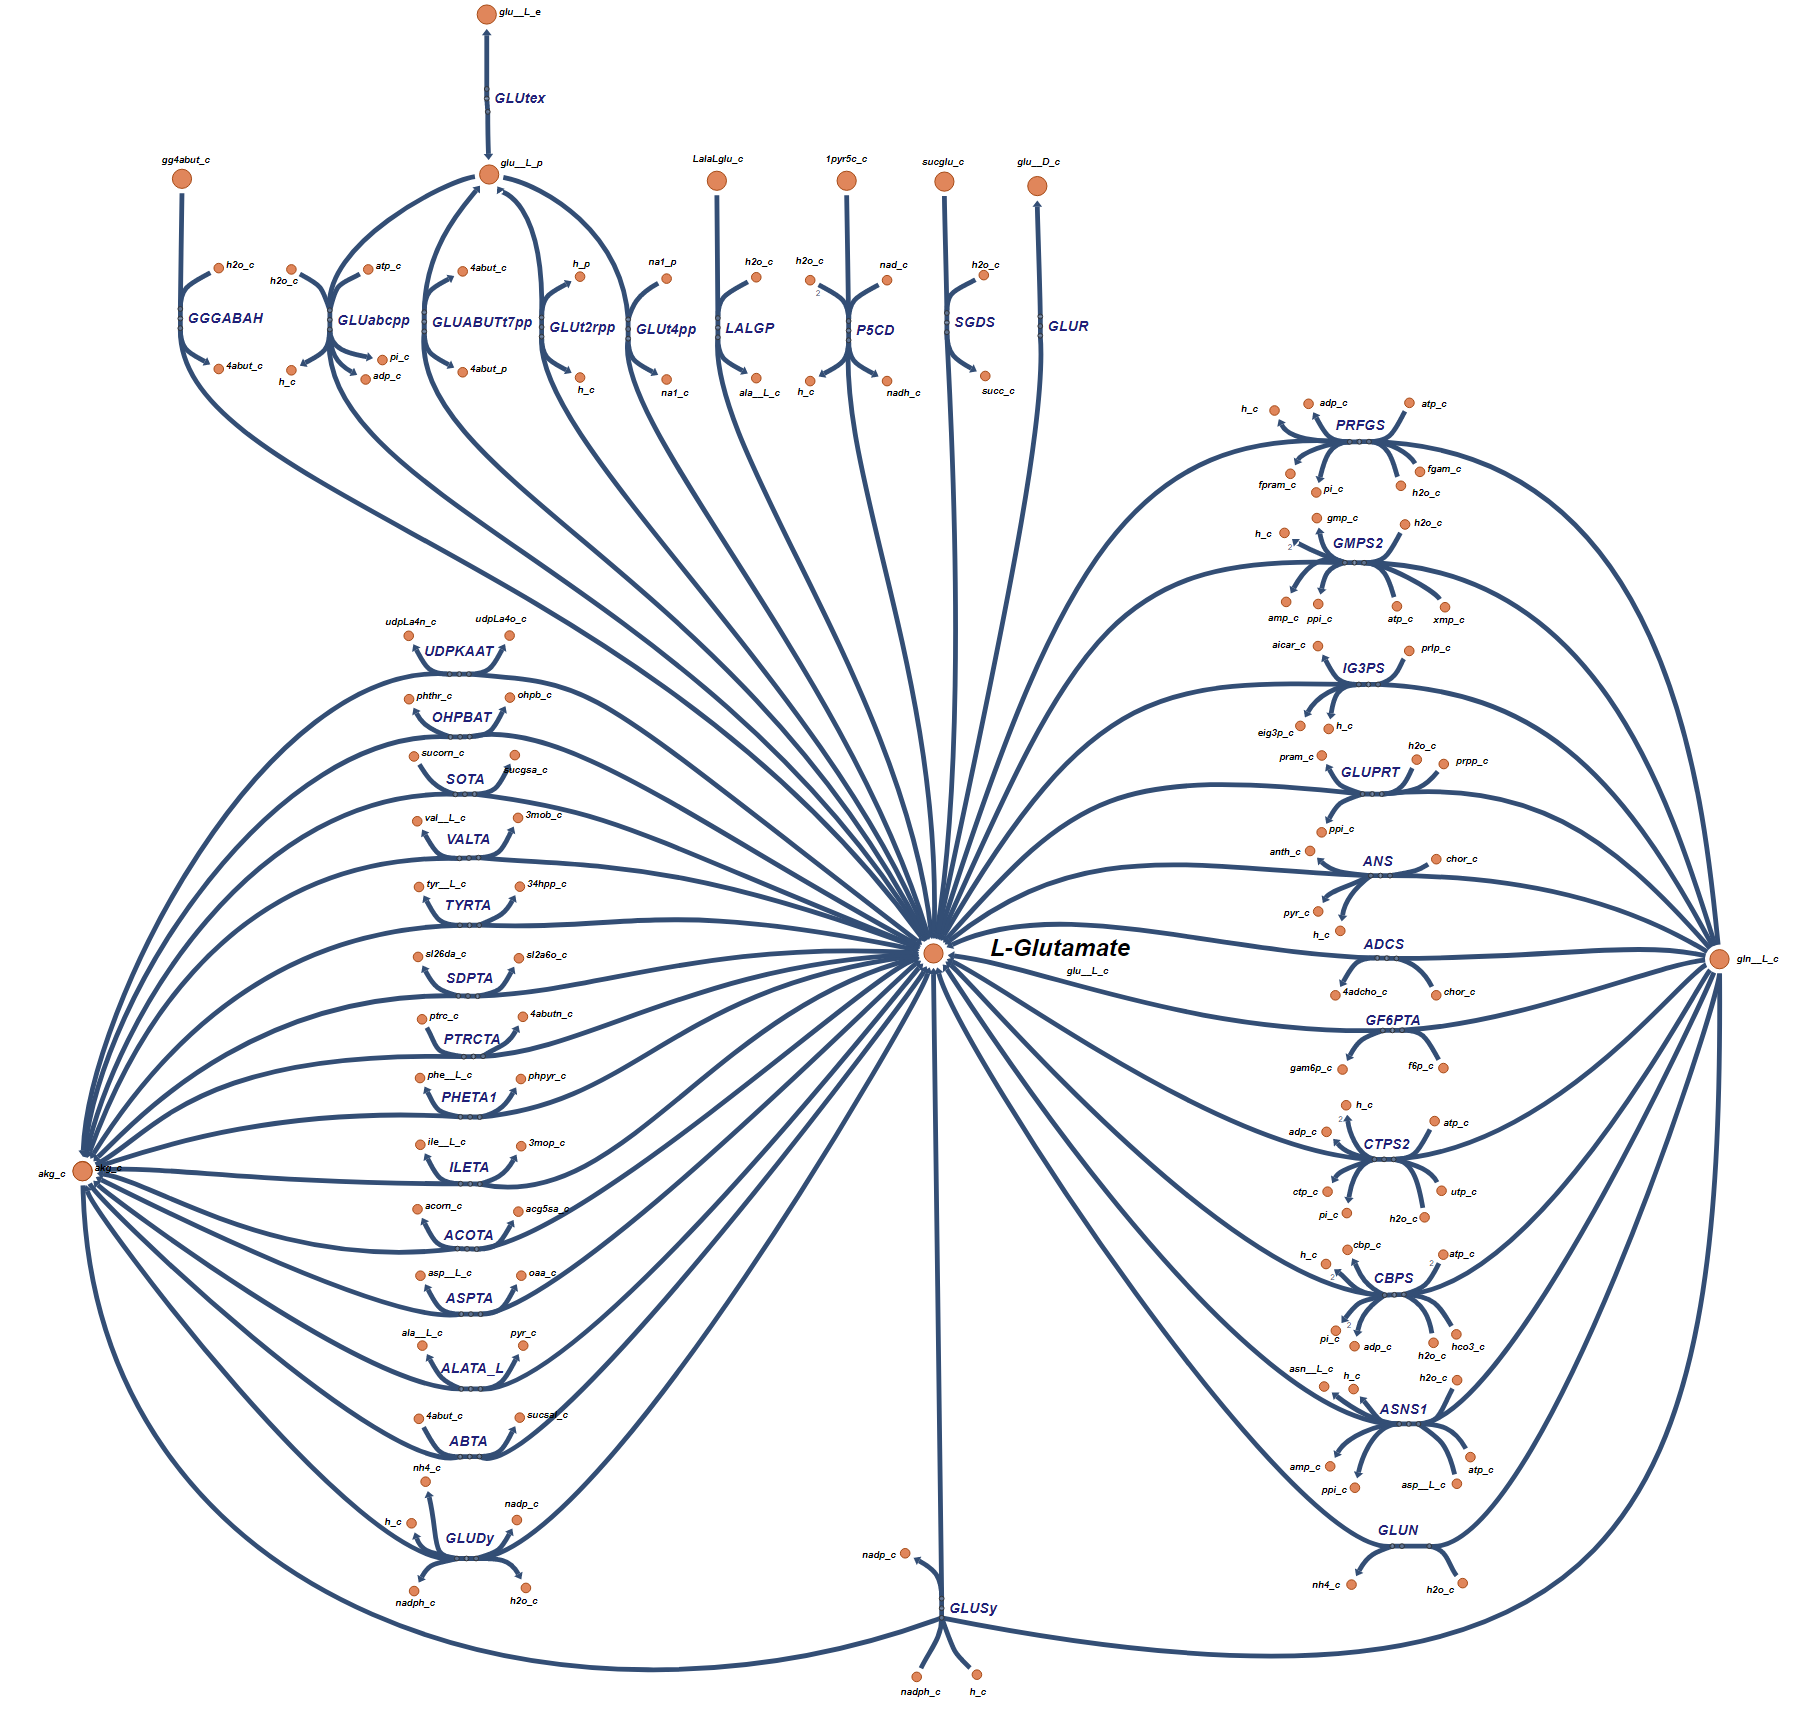

**Figure 3.** The L-Glutamate producing reactions which includes the L-Glutamate "Producing reactions" plus the bidriectional "Consuming reactions".

From this figure, and the suftNet results, we can identify the reactions that can be involved with the biosynthesis of L-Glutamate. They include 'SOTA', 'VALTA', 'TYRTA', 'SDPTA', 'PTRCTA', 'PHETA1', 'ILETA', 'ACOTA', 'ASPTA', 'ALATA_L', 'ABTA', 'GLUDy', 'PRFGS', 'GMPS2', 'IG3PS', 'GLUPRT', 'ANS', 'ADCS', 'GF6PTA', 'CTPS2', 'CBPS', 'ASNS1', 'GLUN', 'GLUSy', 'GGGABAH', 'GLUabcpp', 'GLUABUTt7pp', 'GLUt2rpp', 'GLUt4pp', 'LALGP', 'P5CD', 'SGDS', and 'GLUR'. 

The formulas for these L-Glutamate producing reactions can be found as shown below.

model = saved_model;
glutamateProducingReactions = transpose({'SOTA','VALTA','TYRTA','SDPTA','PTRCTA','PHETA1','ILETA','ACOTA','ASPTA','ALATA_L',...
    'ABTA','GLUDy','PRFGS','GMPS2','IG3PS','GLUPRT','ANS','ADCS','GF6PTA','CTPS2','CBPS','ASNS1','GLUN','GLUSy', ...
    'GGGABAH','GLUabcpp','GLUABUTt7pp','GLUt2rpp','GLUt4pp','LALGP','P5CD','SGDS','GLUR'});
[tmp,glutamateProducing_rxnID] = ismember(glutamateProducingReactions,model.rxns);
reactionNames = model.rxnNames(glutamateProducing_rxnID);
reactionFormulas = printRxnFormula(model,glutamateProducingReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',glutamateProducingReactions)

T = 33×2 table
                                   reactionNames                                                         reactionFormulas                                
               ______________________________________________________    ________________________________________________________________________________

    SOTA       'Succinylornithine transaminase'                          'akg_c + sucorn_c  -> glu__L_c + sucgsa_c '                                     
    VALTA      'Valine transaminase'                                     'akg_c + val__L_c  <=> 3mob_c + glu__L_c '                                      
    TYRTA      'Tyrosine transaminase'                                   'akg_c + tyr__L_c  <=> 34hpp_c + glu__L_c '                                     
    SDPTA      'Succinyldiaminopimelate transaminase'                    'akg_

**Table x.** Table showing the reaction names and reaction formulas for each of the reactions that can produce L-Glutamate.

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(glutamateProducing_rxnID);
T = table(reactionNames,reactionSubsystems,'RowNames',glutamateProducingReactions)

T = 33×2 table
                                   reactionNames                                          reactionSubsystems                 
               ______________________________________________________    ____________________________________________________

    SOTA       'Succinylornithine transaminase'                          'Arginine and Proline Metabolism'                   
    VALTA      'Valine transaminase'                                     'Valine, Leucine, and Isoleucine Metabolism'        
    TYRTA      'Tyrosine transaminase'                                   'Tyrosine, Tryptophan, and Phenylalanine Metabolism'
    SDPTA      'Succinyldiaminopimelate transaminase'                    'Threonine and Lysine Metabolism'                   
    PTRCTA     'Putrescine Transaminase'                                 'A

**Table x.** Subsystems associated with each of the readtions that can produce L-Glutamate. 

Since L-Glutamate is part of nearly every subsytem it is easy to understand the importance of L-Glutamate for cell growth.

The primary biosynthesis pathway includes the reaction 'GLUDy' (Glutamate dehydrogenase (NADP)) which combines ammonium ('nh4_c')  with 2-Oxoglutarate ('akg_c') to create L-Glutamate ('glu__L_c' ). The secondary pathway, 'GLUSy' involves the conversion of L-Glutamine ('gln__L_c')  to L-Glutamate. Below is a list of these reactions and the role the play in the production of L-Glutamate.

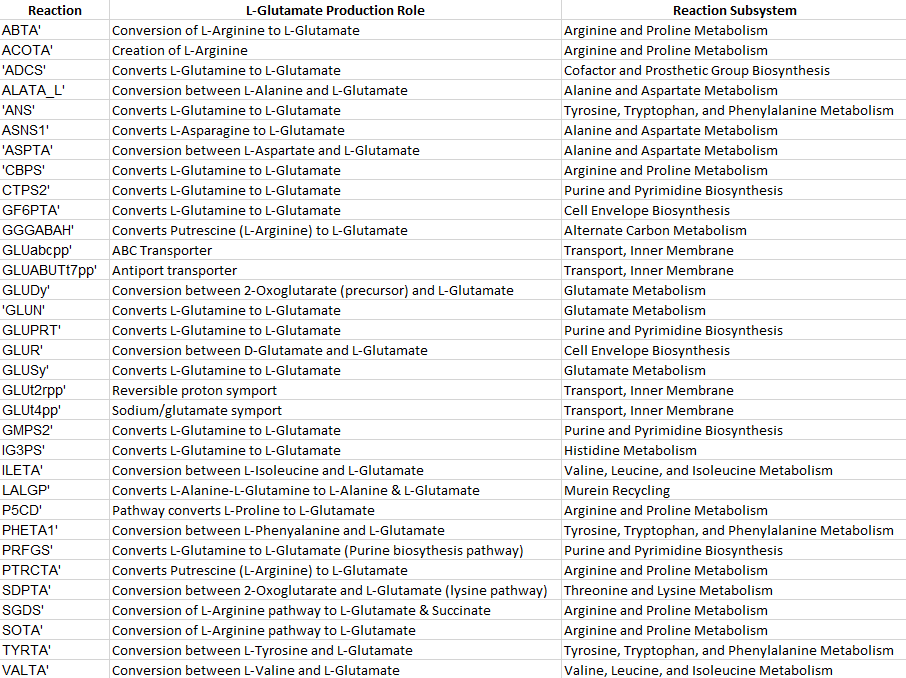

**Table 1.** Potential L-Glutamate producing reactions, their function and the subsystem they are associated with.

Since L-Glutamate is required by most amino acids, let's explore from the "surfNet" results all the reactions that can provide L-Glutamate to other biosyntheis pathways ("Consuming Reactions"). Below is a figure of all the "ConsumingReactions" associated with L-Glutamate.

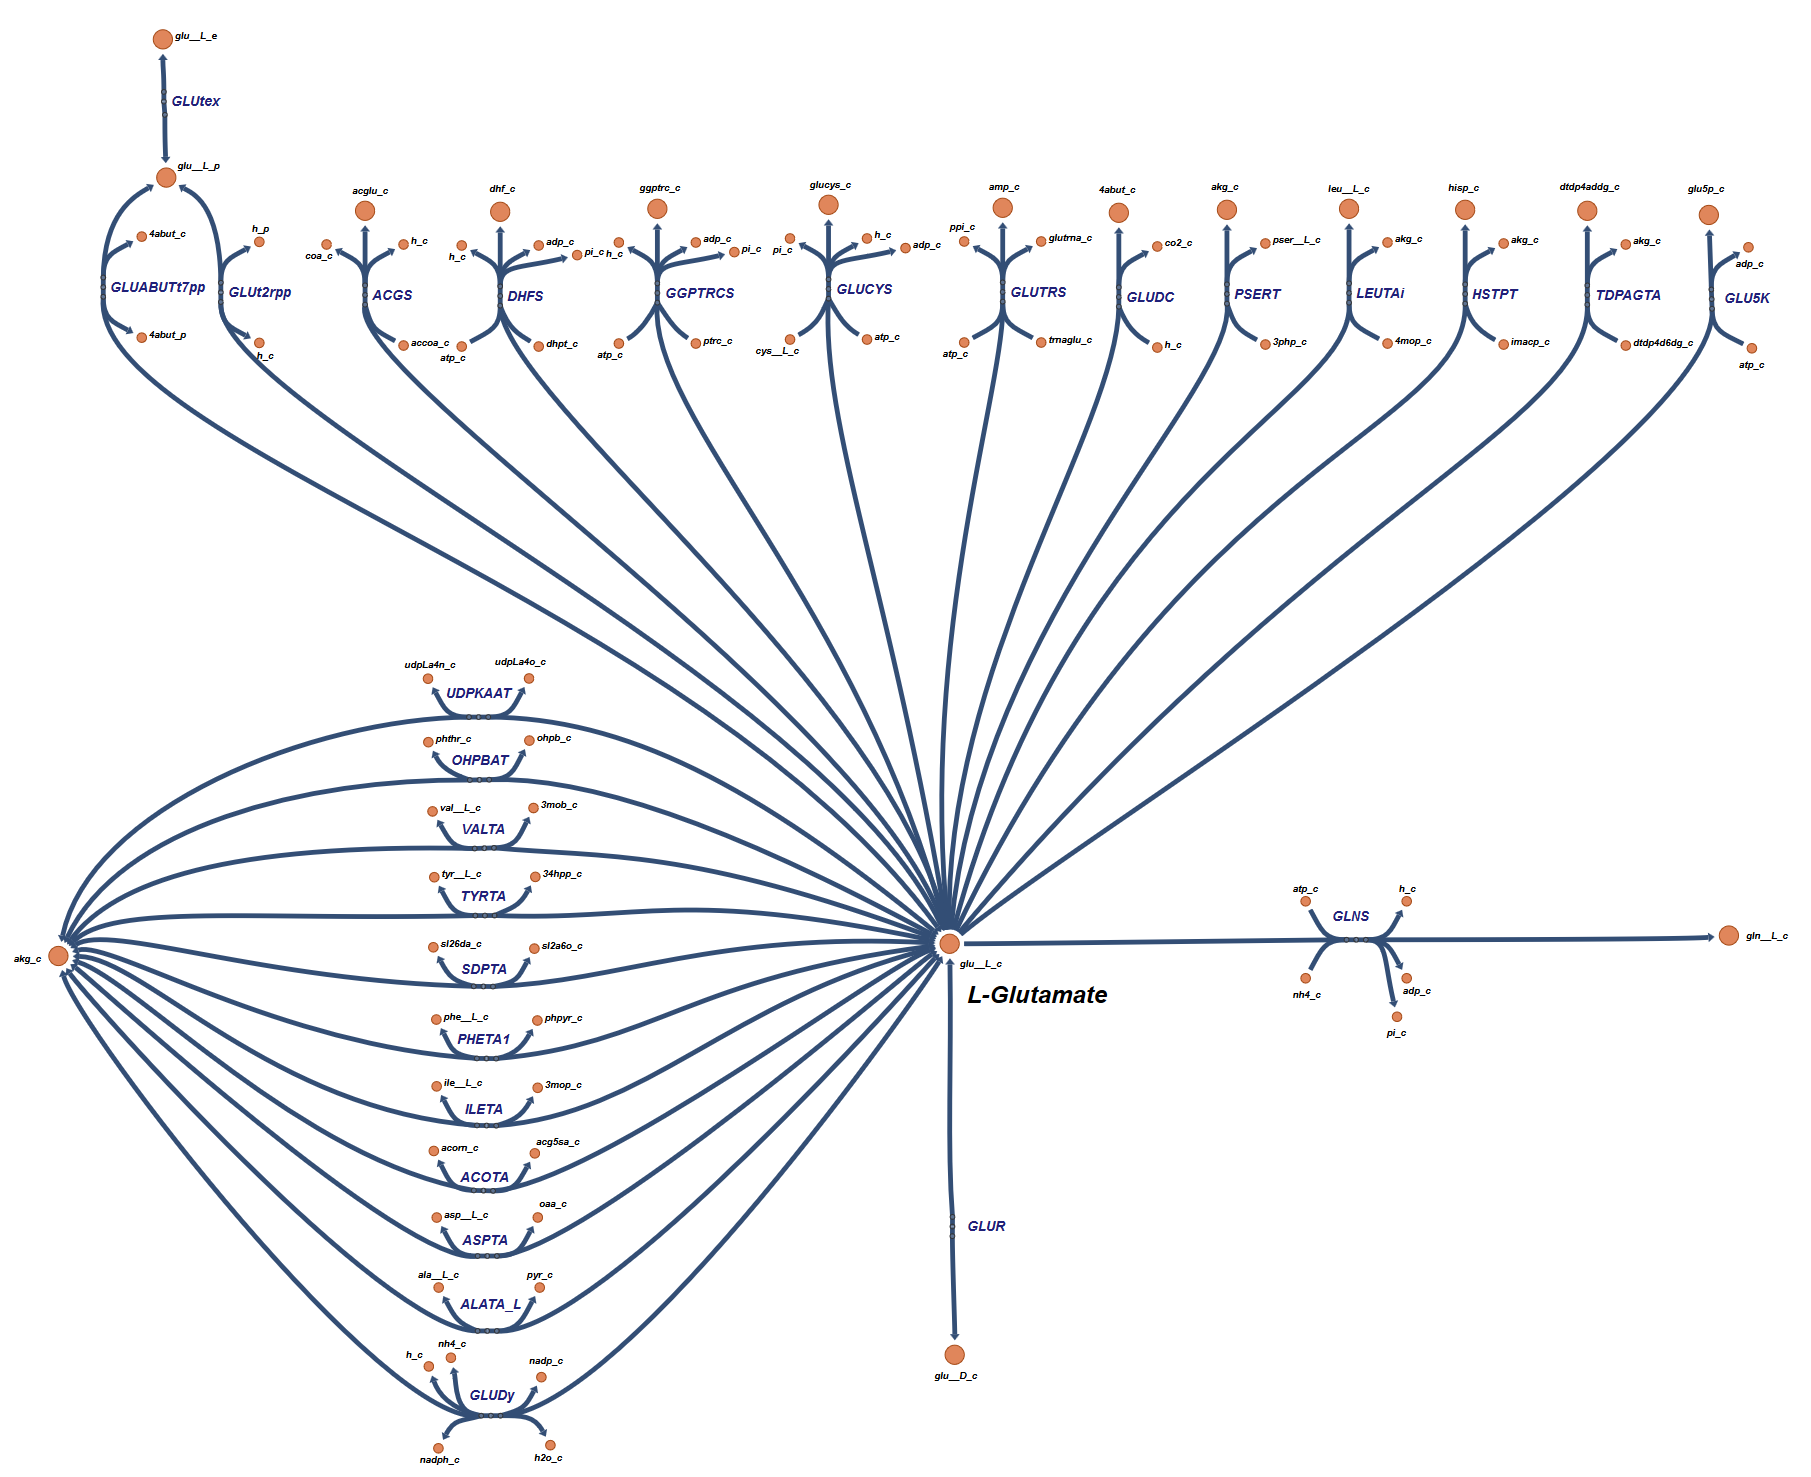

**Figure 4.** The consuming reactions associated with L-Glutamate.

From this figure, and the suftNet results, we can identify the "Consuming Reactions" of L-Glutamate. They include 'ACGS', 'ACOTA', 'ALATA_L', 'ASPTA', 'DHFS', 'GGPTRCS', 'GLNS','GLU5K', 'GLUABUTt7pp', 'GLUCYS', 'GLUDC', 'GLUDy', 'GLUR', 'GLUt2rpp', 'GLUTRS', 'HSTPT', 'ILETA', 'LEUTAi', 'OHPBAT', 'PHETA1', 'PSERT', 'SDPTA', 'TDPAGTA', 'TYRTA', 'UDPKAAT', 'VALTA'. The formulas for these L-Glutamate "Consuming Reactions" can be found as shown below.

model = saved_model;
glutamateConsumingReactions = transpose({'ACGS','ACOTA','ALATA_L','ASPTA','DHFS','GGPTRCS','GLNS','GLU5K','GLUABUTt7pp',...
    'GLUCYS','GLUDC','GLUDy','GLUR','GLUt2rpp','GLUTRS','HSTPT','ILETA','LEUTAi','OHPBAT','PHETA1','PSERT','SDPTA',...
    'TDPAGTA','TYRTA','UDPKAAT','VALTA'});
[tmp,glutamateConsuming_rxnID] = ismember(glutamateConsumingReactions,model.rxns);
reactionNames = model.rxnNames(glutamateConsuming_rxnID);
reactionFormulas = printRxnFormula(model,glutamateConsumingReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',glutamateConsumingReactions)

T = 26×2 table
                                             reactionNames                                                       reactionFormulas                        
                   __________________________________________________________________    ________________________________________________________________

    ACGS           'N-acetylglutamate synthase'                                          'accoa_c + glu__L_c  -> acglu_c + coa_c + h_c '                 
    ACOTA          'Acetylornithine transaminase'                                        'acorn_c + akg_c  <=> acg5sa_c + glu__L_c '                     
    ALATA_L        'L-alanine transaminase'                                              'akg_c + ala__L_c  <=> glu__L_c + pyr_c '                       
    ASPTA          'Aspartate transaminase'                                   

We can also find the subsystems that are associated with each of these "Consuming Reactions".

reactionSubsystems = model.subSystems(glutamateConsuming_rxnID);
T = table(reactionNames,reactionSubsystems,'RowNames',glutamateConsumingReactions)

T = 26×2 table
                                             reactionNames                                            reactionSubsystems             
                   __________________________________________________________________    ____________________________________________

    ACGS           'N-acetylglutamate synthase'                                          'Arginine and Proline Metabolism'           
    ACOTA          'Acetylornithine transaminase'                                        'Arginine and Proline Metabolism'           
    ALATA_L        'L-alanine transaminase'                                              'Alanine and Aspartate Metabolism'          
    ASPTA          'Aspartate transaminase'                                              'Alanine and Aspartate Metabolism'          
    DHFS           'Dihydro

Below is a table that shows the role of the different consuming reactions.

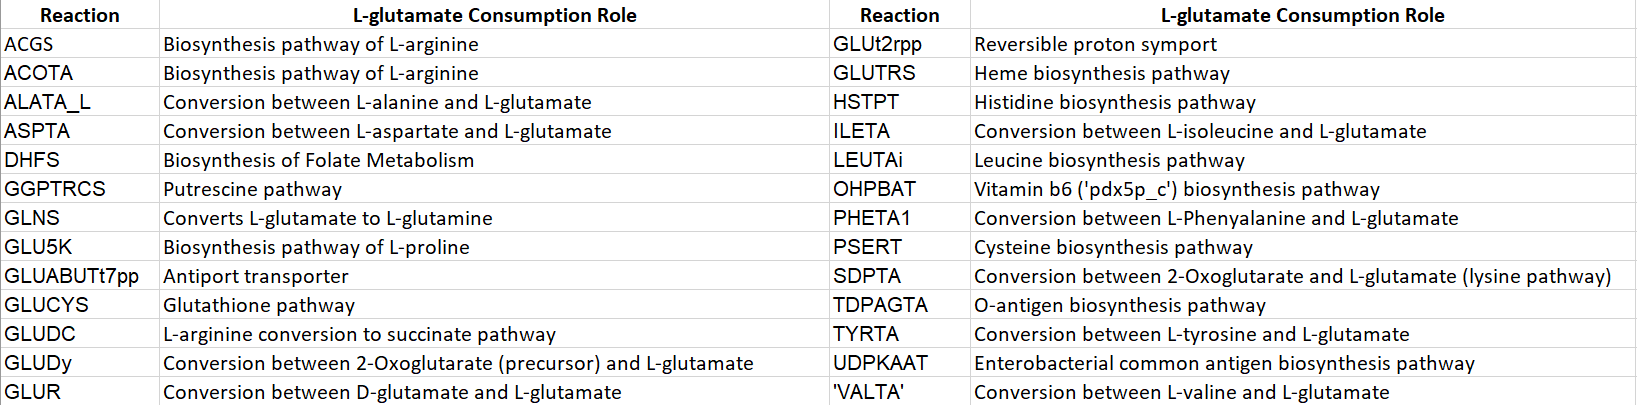

**Table 2.** Potential L-Glutamate "Consuming Reactions" and the role they play in the cell.

## 3.2 L-Glutamate Aerobic Operation

Under aerobic conditions we see the following fluxes.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
glutamateReactions = transpose({'SOTA','VALTA','TYRTA','SDPTA','PTRCTA','PHETA1','ILETA','ACOTA','ASPTA','ALATA_L',...
    'ABTA','GLUDy','PRFGS','GMPS2','IG3PS','GLUPRT','ANS','ADCS','GF6PTA','CTPS2','CBPS','ASNS1','GLUN','GLUSy', ...
    'GGGABAH','GLUabcpp','GLUABUTt7pp','GLUt2rpp','GLUt4pp','LALGP','P5CD','SGDS','GLUR'});
[tmp,glutamate_rxnID] = ismember(glutamateReactions,model.rxns);
printLabeledData(glutamateReactions, round(FBAsolution.x(glutamate_rxnID),3))

SOTA	0	
VALTA	-0.416	
TYRTA	-0.136	
SDPTA	-0.364	
PTRCTA	0	
PHETA1	-0.182	
ILETA	-0.285	
ACOTA	-0.291	
ASPTA	-2.876	
ALATA_L	-0.571	
ABTA	0	
GLUDy	-8.401	
PRFGS	0.44	
GMPS2	0.239	
IG3PS	0.093	
GLUPRT	0.44	
ANS	0.056	
ADCS	0.001	
GF6PTA	0.093	
CTPS2	0.158	
CBPS	0	
ASNS1	0	
GLUN	0	
GLUSy	0	
GGGABAH	0	
GLUabcpp	0	
GLUABUTt7pp	-0	
GLUt2rpp	0	
GLUt4pp	0	
LALGP	0	
P5CD	0	
SGDS	0	
GLUR	-0.027	


The fluxes for both the producing and consuming reactions can be calculated as follows.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
glutamateReactions = transpose({'HSTPT','LEUTAi','PSERT','TDPAGTA','GLUDy','OHPBAT','UDPKAAT',...
    'ABTA','PTRCTA','SOTA','ACOTA','ALATA_L','ASPTA','ILETA','PHETA1','SDPTA','TYRTA','VALTA','GLUSy',...
    'GLNS','ADCS','ANS','ASNS1','CBPS','CTPS2','GF6PTA','GLUN','GLUPRT','GMPS2','IG3PS','PRFGS',...
    'ACGS','DHFS','GGPTRCS','GLU5K','GLUCYS','GLUDC','GLUTRS','GGGABAH','LALGP','P5CD','SGDS','GLUabcpp','GLUt4pp',...
    'GLUABUTt7pp','GLUt2rpp','GLUR','GLUtex','EX_glu__L_e'});
[tmp,glutamate_rxnID] = ismember(glutamateReactions,model.rxns);
printLabeledData(glutamateReactions, round(FBAsolution.x(glutamate_rxnID),3))

HSTPT	0.093	
LEUTAi	0.443	
PSERT	1.688	
TDPAGTA	0	
GLUDy	-8.401	
OHPBAT	0	
UDPKAAT	0	
ABTA	0	
PTRCTA	0	
SOTA	0	
ACOTA	-0.291	
ALATA_L	-0.571	
ASPTA	-2.876	
ILETA	-0.285	
PHETA1	-0.182	
SDPTA	-0.364	
TYRTA	-0.136	
VALTA	-0.416	
GLUSy	0	
GLNS	1.779	
ADCS	0.001	
ANS	0.056	
ASNS1	0	
CBPS	0	
CTPS2	0.158	
GF6PTA	0.093	
GLUN	0	
GLUPRT	0.44	
GMPS2	0.239	
IG3PS	0.093	
PRFGS	0.44	
ACGS	0.291	
DHFS	0.001	
GGPTRCS	0	
GLU5K	0.217	
GLUCYS	0	
GLUDC	0	
GLUTRS	0.004	
GGGABAH	0	
LALGP	0	
P5CD	0	
SGDS	0	
GLUabcpp	0	
GLUt4pp	0	
GLUABUTt7pp	-0	
GLUt2rpp	0	
GLUR	-0.027	
GLUtex	0	
EX_glu__L_e	0	


These fluxes are better seen in the following Escher-based visualization.

The value of this designation is seen in the next figure which shows the flux values through the  pathways for aerobic operation. In reading this figure, the flux though unidirectional consuming reactions will aways be positive (red) as the flux moves away from or reducing the L-Glutamate pool. On the other hand, the flux though unidirectional producing reactions will aways be positive (red) as the flux moves towards or adds to the L-Glutamate pool. For the case of the bidirectional "Consuming" reactions, the forward direction is away from the L-Glutamate pool which would show on the figure as positive or red, while a blue color would indicate that the flux is going in the reverse direction adding to the pool. Finally, for the case of a bidirectional "Producing" reaction, the forward direction (red) is towards the L-Glutamate pool with the color blue showing the reverse direction of the flux away from the L-Glutamate pool. (Total_Glutamate_Biosynthesis_Aerobic_Flux.json or Total_Glutamate_Biosynthesis_Aerobic_Flux.svg or Total_Glutamate_Biosynthesis_Aerobic_Flux.png)

**Figure x.** Aerobic fluxes flowing through the L-Glutamate biosynthesis pathways.

In this figure we can see that the primary pathways for the biosyntheis pathways is through 'GLUDy' (bright red) which is operating in reverse mode. The primary consumer of L-Glutamate is through 'GLNS' for the production of L-Glutamine and 'PSERT' (bright red) that is part of teh pathway for the production of L-Serine, L-Glycine, and L-Cysteine . From this figure you can see that there are many other pathways that both consume and produce L-Glutamate.

Another method for identifying these aerobic fluxes is through the "surfNet" COBRA toolbox function.

surfNet(model, 'glu__L_c',0,FBAsolution.x,1,1)


Met #544  glu__L_c, L-Glutamate, C5H8NO4
Consuming reactions with non-zero fluxes :
#8  BIOMASS_Ec_iJO1366_core_53p95M  E. coli biomass objective function (iJO1366) - core - with 53.95 GAM estimate  (0.982372)
  0.000223 10fthf_c + 2.6e-05 2fe2s_c + 0.000223 2ohph_c + 0.00026 4fe4s_c 
  + 0.51369 ala__L_c + 0.000223 amet_c + 0.29579 arg__L_c + 0.24105 asn__L_c 
  + 0.24105 <a href="matlab: surfNet([],'asp__L_c',0,[],1, 1, 65);">asp__L_c</

It should be pointed out that over 90% of the cell's nitrogen flows through the L-Glutamate pathway. 

## 3.3 Excess L-Glutamate Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Glutamate for the desired bioproduct.  What is the maximum amount of excess L-Glutamate, beyond what the cell needs for normal growth, that can be produced for a given growth-rate? This is accomplished by adding a demand reaction for L-Glutamate ('DM_glu__L_c') and then maximizing the flux through the demand reaction for a given cellular growth-rate. Maximizing the flux through the demand reaction can be accomplished by setting the demand reaction as the objective function. This is illustrated in the code below.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'glu__L_c');

DM_glu__L_c	glu__L_c 	->	


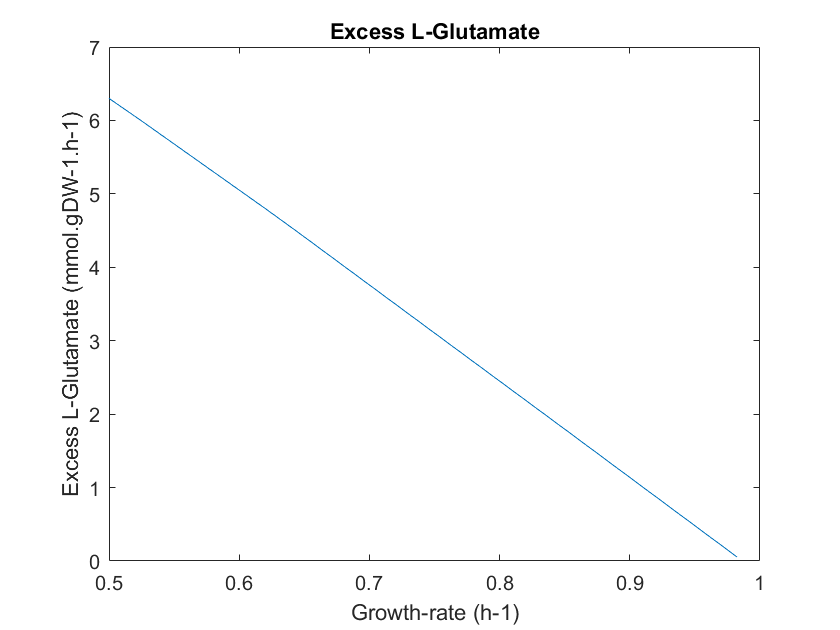

[tmp,alanine_MAX_rxnID] = ismember({'DM_glu__L_c'},model.rxns);
model = changeObjective(model,'DM_glu__L_c'); % Set the objective function
FBAsolution_Glutamate = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessGlutamate = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Glutamate = optimizeCbModel(model,'max'); % Perform FBA
    excessGlutamate(i) = FBAsolution_Glutamate.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessGlutamate)
title('Excess L-Glutamate'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Glutamate (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of excess L-Glutamate that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Glutamate increases the growth-rate will need to decrease. In this figure we can see that the excess L-Glutamate flux can increase from 0.0545 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 6.3 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Glutamate flux beyond these levels will require using the pathways that allow for the transport of L-Glutamate from the extracellular media. The amount of excess L-Glutamate that can be produced by a cell can be important in the production of recombinant proteins. This excess amino acid capability of the cell will be one of the limiting factors in the amount of recombinant protein that can be produced. For the case of L-glutatmate, not only will the recombinant protein potentially require a certain percentage of L-Glutamate amino acids, but the biosynthesis of most amino acids will require L-Glutamate to provide their amino group which signficantly increases the requirement for excess L-Glutamate.

## **4. L-Glutamine Biosynthesis**

The chemical structure for L-Glutamine is shown below. 

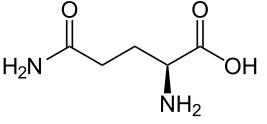

**Figure 6**. The chemical structure for L-Glutamine is ${\mathrm{C}}_5 {\mathrm{H}}_{10} {\mathrm{O}}_3 N_2$ (Wikipedia)

Let's identify the "producing" and "consuming" reactions associated with L-Glutamine using "surfNet" COBRA toolbox function.

surfNet(model, 'gln__L_c')


Met #541  gln__L_c, L-Glutamine, C5H10N2O3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

The reactions that are used in the production of L-Glutamine are shown below.

## 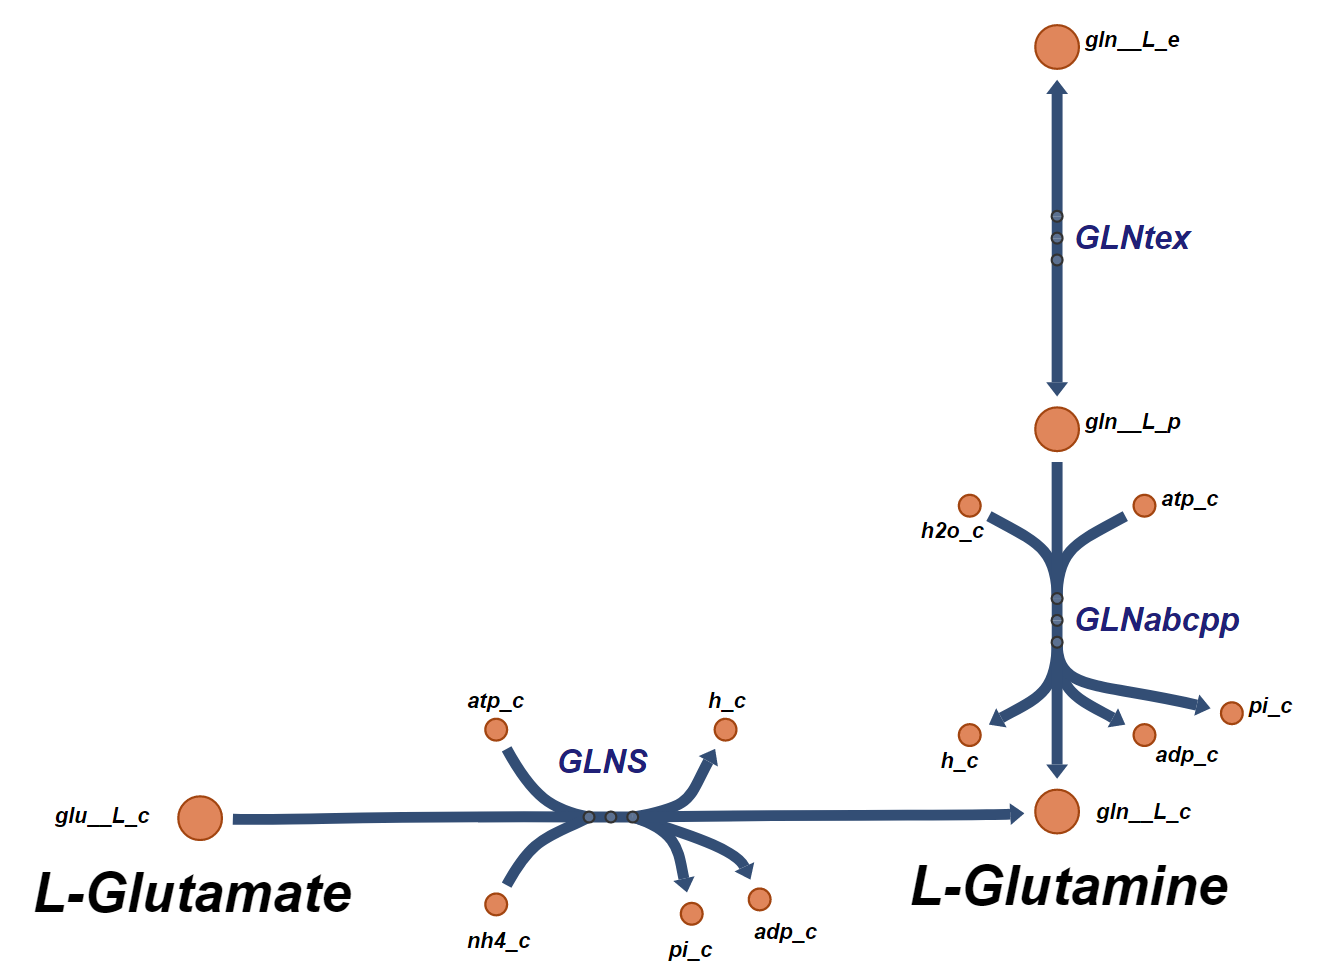

**Figure 7. **The reactions associated with the biosynthesis of L-Glutamine.

Since L-Glutamine is one of the key providers of nitrogen, along with L-Glutamate, let's looks at both the "producing" and "consuming" reactions and identify the pathways they serve. Below is an Escher-based [3] map of the reactions that both produce and consume L-glutamate.

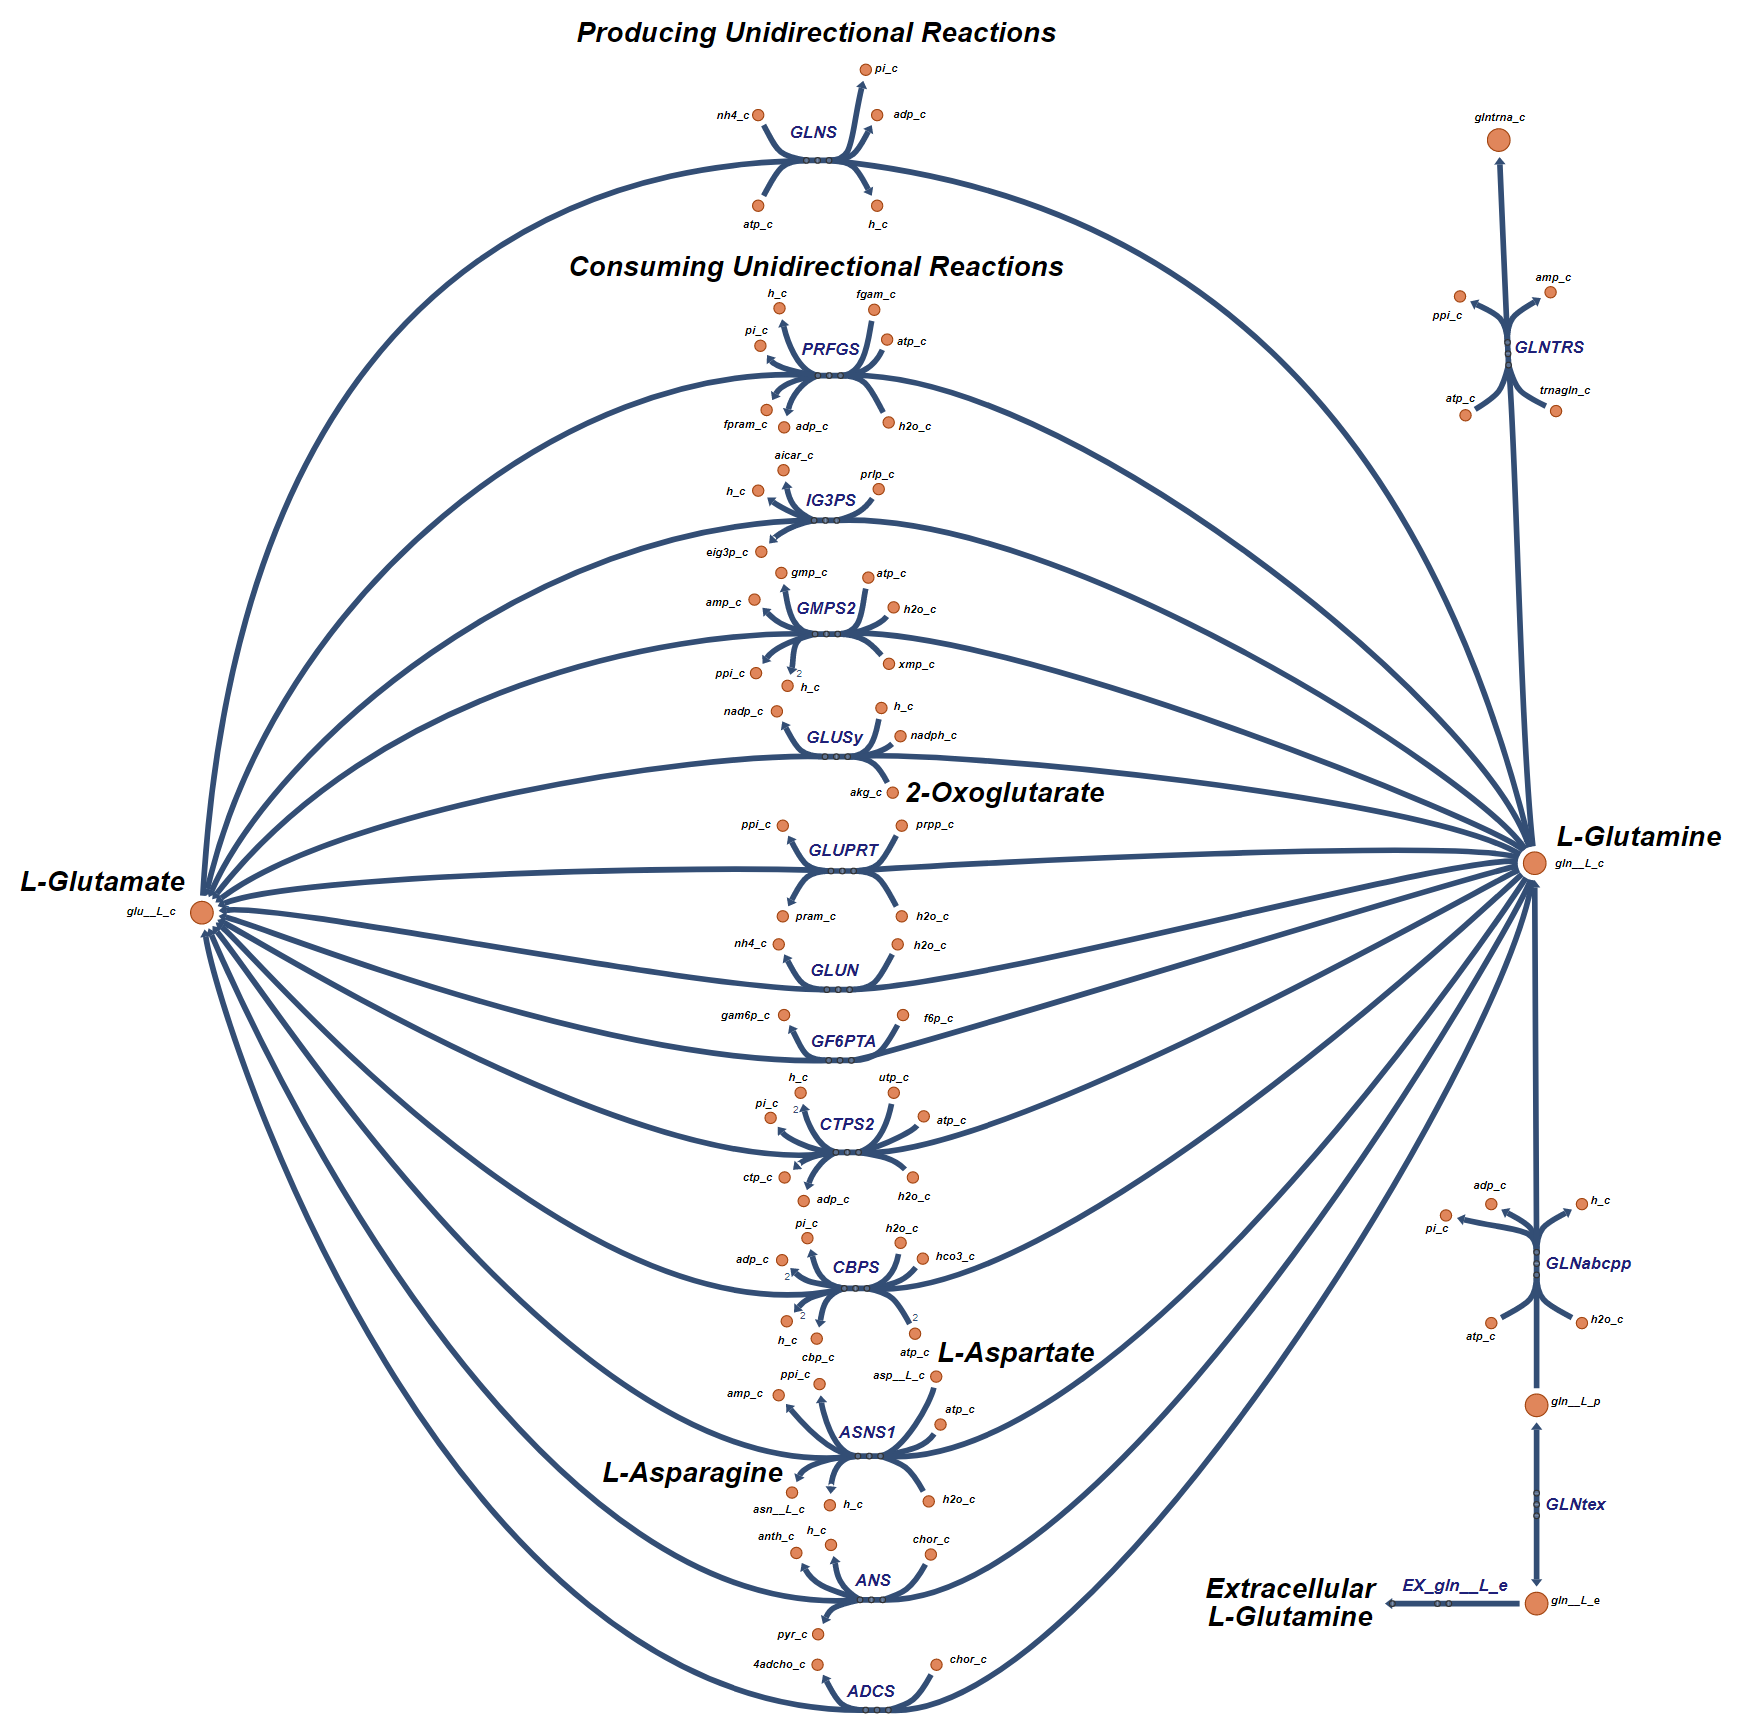

**Figure 8**. A map of the reactions that consume L-glutamate.

From this figure, and the suftNet results, we can identify the "Producing" and "Consuming" reactions of L-Glutamine. They include ''ADCS', 'ANS', 'ASNS1', 'CBPS', 'CTPS2', 'GF6PTA', 'GLUN', 'GLUPRT', 'GLUSy', 'GMPS2', 'IG3PS', 'PRFGS', 'GLNS', 'GLNTRS', 'GLNabcpp', 'GLNtex', and 'EX_gln__L_e'

The formulas for these L-Glutamate "Consuming Reactions" can be found as shown below.

model = saved_model;
glutamineReactions = transpose({'ADCS','ANS','ASNS1','CBPS','CTPS2','GF6PTA','GLUN','GLUPRT','GLUSy','GMPS2','IG3PS','PRFGS',...
    'GLNS','GLNTRS','GLNabcpp','GLNtex','EX_gln__L_e'});
[tmp,glutamine_rxnID] = ismember(glutamineReactions,model.rxns);
reactionNames = model.rxnNames(glutamine_rxnID);
reactionFormulas = printRxnFormula(model,glutamineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',glutamineReactions)

T = 17×2 table
                                          reactionNames                                                                 reactionFormulas                                  
                __________________________________________________________________    ____________________________________________________________________________________

    ADCS        '4-amino-4-deoxychorismate synthase'                                  'chor_c + gln__L_c  -> 4adcho_c + glu__L_c '                                        
    ANS         'Anthranilate synthase'                                               'chor_c + gln__L_c  -> anth_c + glu__L_c + h_c + pyr_c '                            
    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'asp__L_c + atp_c + gln__L_c + h2o_c  -> amp_c + asn__L_c + glu__L_c + h_c + ppi_c '
    

We can also find the subsystems associated with each of these "Producing" and "Consuming" reactions of L-Glutamine.

reactionSubsystems = model.subSystems(glutamine_rxnID);
T = table(reactionNames,reactionSubsystems,'RowNames',glutamineReactions)

T = 17×2 table
                                          reactionNames                                                reactionSubsystems                 
                __________________________________________________________________    ____________________________________________________

    ADCS        '4-amino-4-deoxychorismate synthase'                                  'Cofactor and Prosthetic Group Biosynthesis'        
    ANS         'Anthranilate synthase'                                               'Tyrosine, Tryptophan, and Phenylalanine Metabolism'
    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'Alanine and Aspartate Metabolism'                  
    CBPS        'Carbamoyl-phosphate synthase (glutamine-hydrolysing)'                'Arginine and Proline Metabolism'                   
    CT

## 4.2. L-Glutamine Aerobic Operation

Under aerobic conditions we see the following fluxes.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
[tmp,glutamate_rxnID] = ismember(glutamateReactions,model.rxns);
printLabeledData(glutamineReactions, round(FBAsolution.x(glutamine_rxnID),3))

ADCS	0.001	
ANS	0.056	
ASNS1	0	
CBPS	0	
CTPS2	0.158	
GF6PTA	0.093	
GLUN	0	
GLUPRT	0.44	
GLUSy	0	
GMPS2	0.239	
IG3PS	0.093	
PRFGS	0.44	
GLNS	1.779	
GLNTRS	0	
GLNabcpp	0	
GLNtex	0	
EX_gln__L_e	0	


These fluxes are better seen in the following Escher-based visualization.

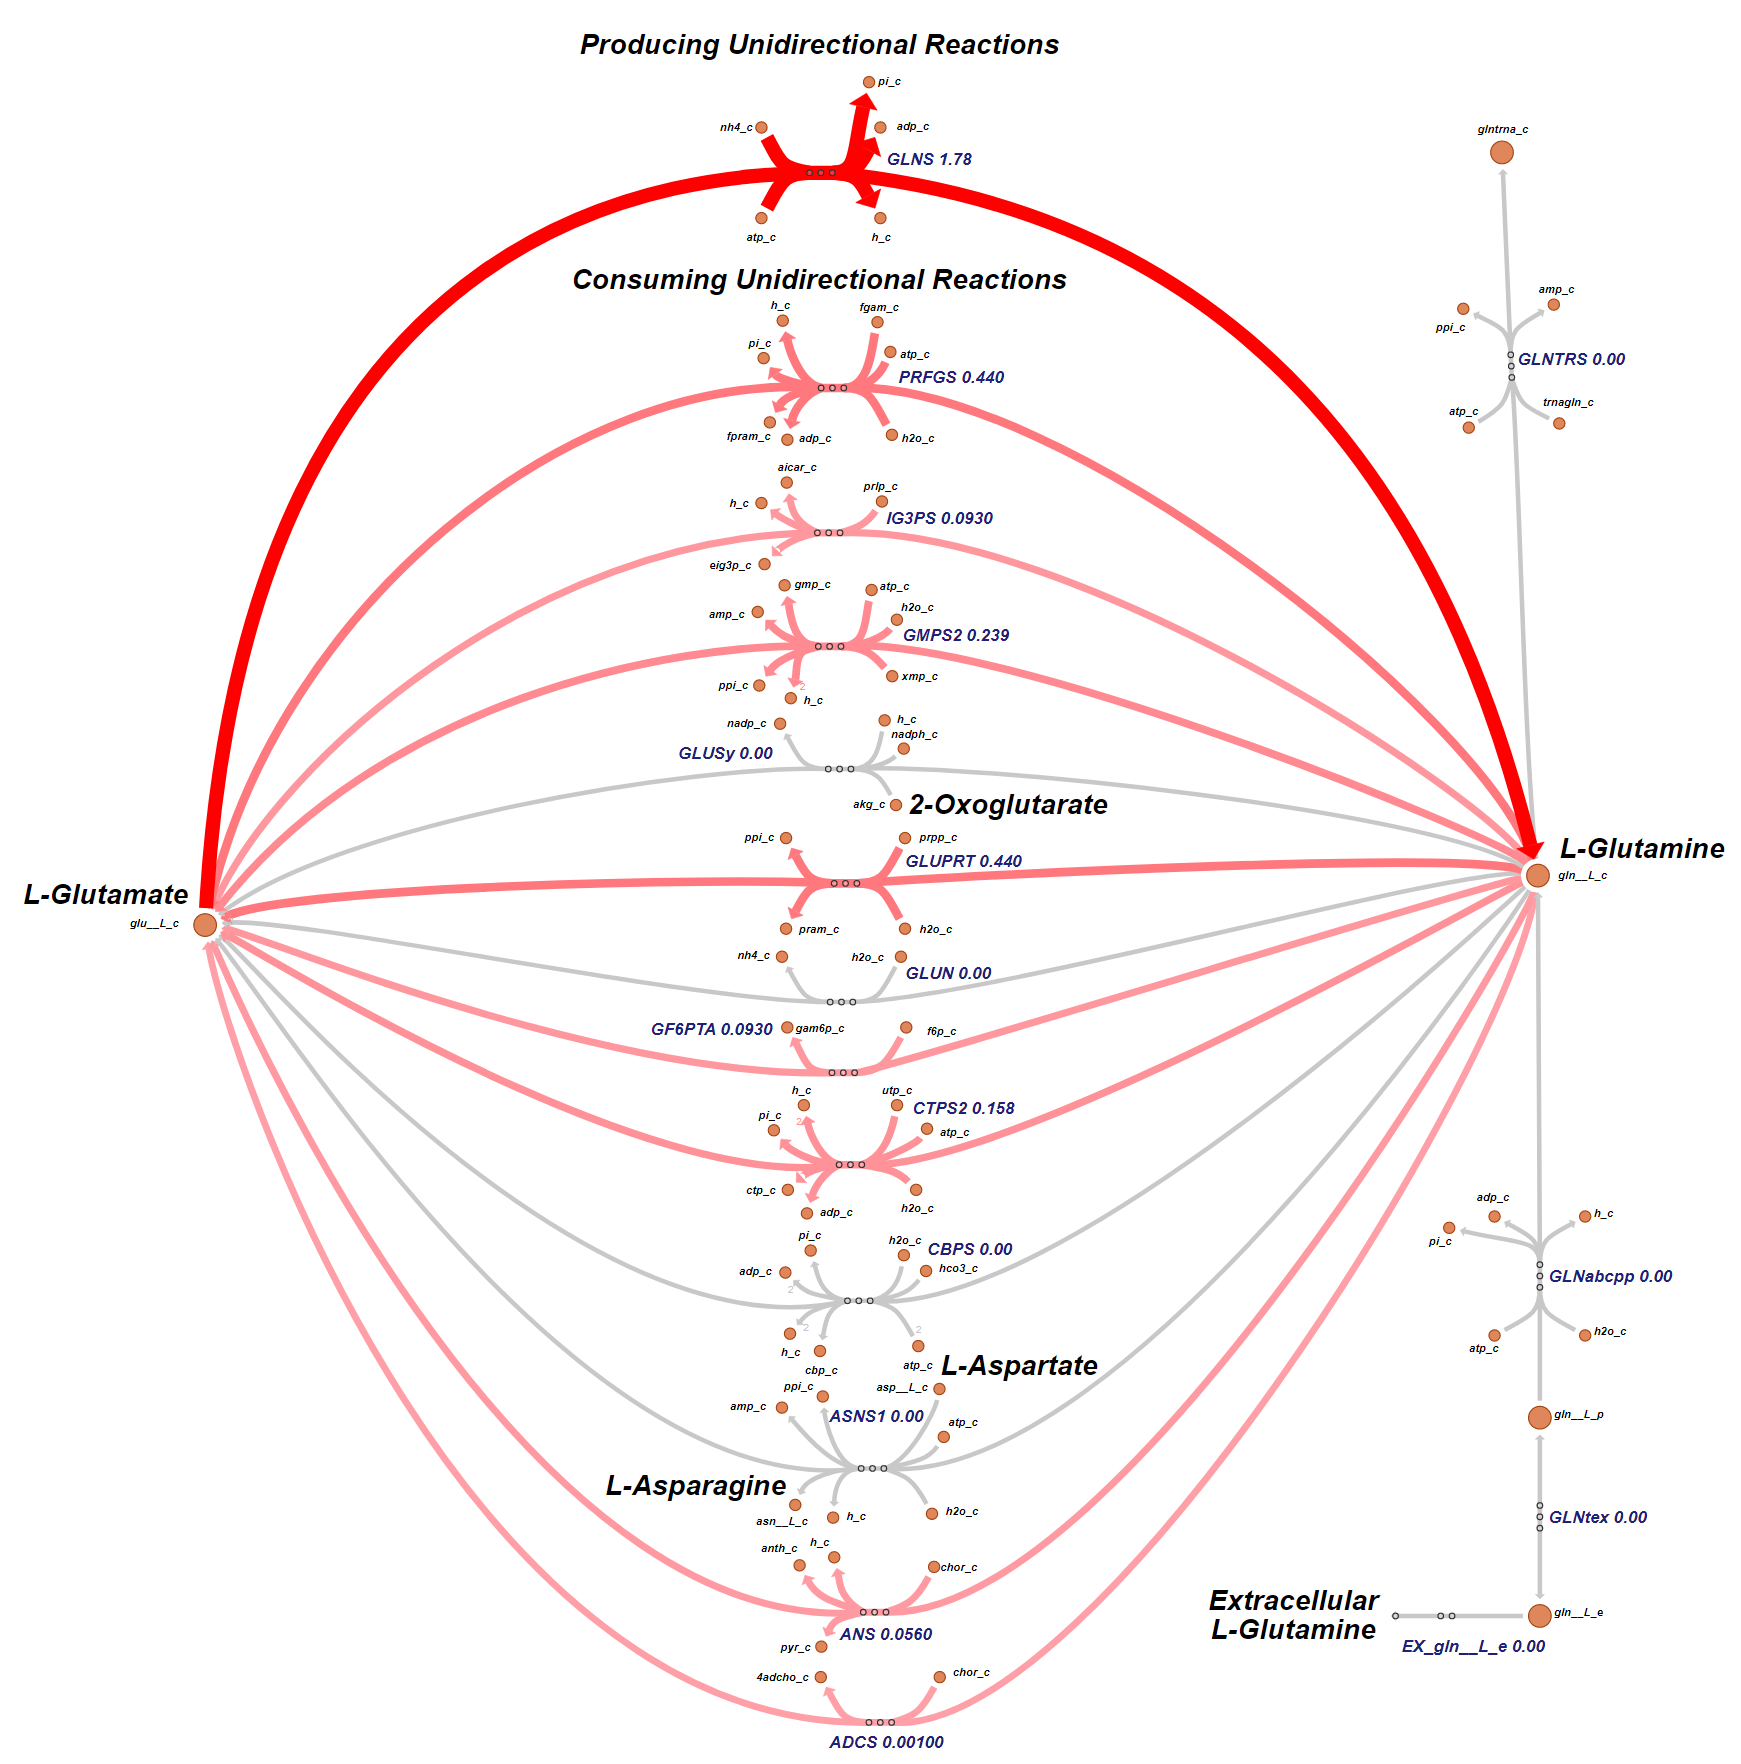

**Figure x.** Escher visualization of the aerobic fluxes flowing through the L-Glutamine biosynthesis pathways (Gutamine_Biosynthesis_Total_Aerobic.png or Gutamine_Biosynthesis_Total_Aerobic.svg).

In this figure we can see that the primary pathway for the biosyntheis pathways is through 'GLNS' (thick red line). The consumers of L-Glutamine are shown with the lighter/thinner red lines. 

## 4.3 Excess L-Glutamine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Glutamine for the desired bioproduct.  What is the maximum amount of excess L-Glutamine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'gln__L_c');

DM_gln__L_c	gln__L_c 	->	


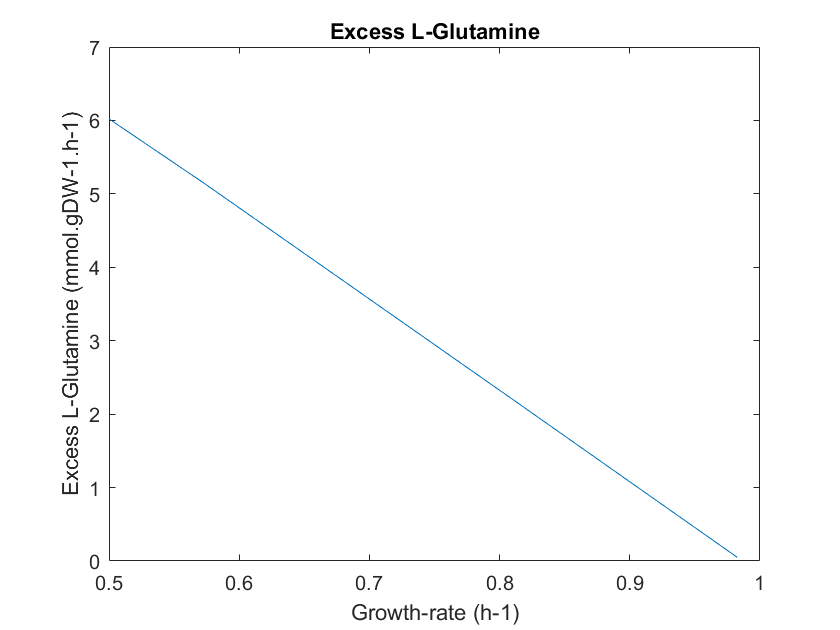

[tmp,Glutamine_MAX_rxnID] = ismember({'DM_gln__L_c'},model.rxns);
model = changeObjective(model,'DM_gln__L_c'); % Set the objective function
FBAsolution_Glutamine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessGlutamine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Glutamine = optimizeCbModel(model,'max'); % Perform FBA
    excessGlutamine(i) = FBAsolution_Glutamine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessGlutamine)
title('Excess L-Glutamine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Glutamine (mmol.gDW-1.h-1)');

**Figure 9. **A plot showing the maximum amount of L-Glutamine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Glutamine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Glutamine flux can increase from 0.09824 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 6.021 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Glutamine flux beyond these levels will require using the pathways that allow for the transport of L-Glutamine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

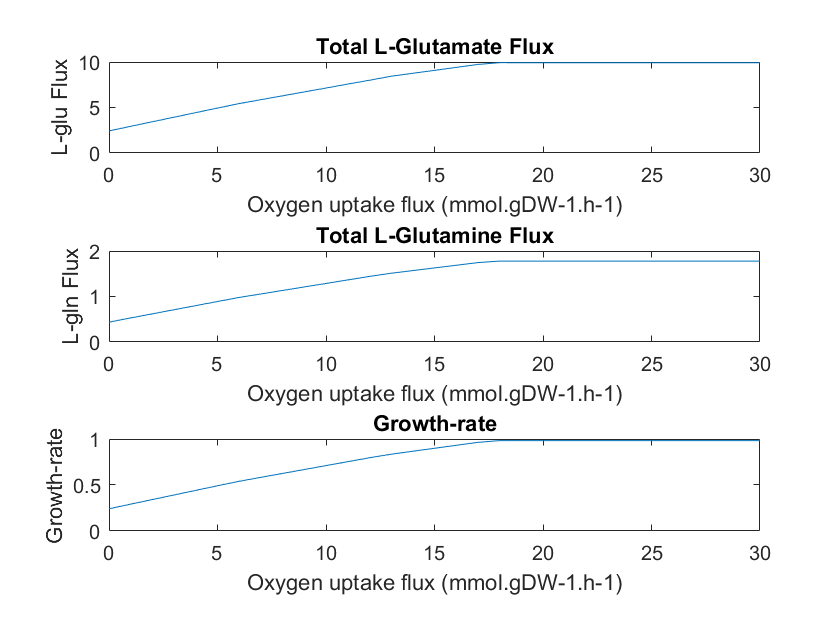

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
glu_flux = [];
gln_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'glu__L_c'}, FBAsolution.x);
    glu_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'gln__L_c'}, FBAsolution.x);
    gln_flux(k) = sum(vP);   
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(3,1,1); % top subplot
ax2 = subplot(3,1,2); % middle subplot
ax3 = subplot(3,1,3); % bottom subplot

plot(ax1,oFlux,glu_flux)
title(ax1,'Total L-Glutamate Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'L-glu Flux');

plot(ax2,oFlux,gln_flux);
title(ax2,'Total L-Glutamine Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'L-gln Flux'); 

plot(ax3,oFlux,growthRate);
title(ax3,'Growth-rate'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'Growth-rate'); 

**Figure 10.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

## 5. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Glutamate Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-Glutamate and L-Glutamine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):

- M. Schaechter et al, "Microbe", ASM Press, 2006, p.119.

- D. White, "The physiology and biochemistry of prokaryotes," 3rd edition, Oxford University Press, 2007.